# Kmeans Clustering of Financial Data

*k-means clustering*, or Lloyd’s algorithm [[2]](https://www.mathworks.com/help/releases/R2021a/stats/kmeans.html#bues3lh), is an iterative, data-partitioning algorithm that assigns *n* observations to exactly one of *k* clusters defined by centroids, where *k* is chosen before the algorithm starts.

The algorithm proceeds as follows:

- Choose *k* initial cluster centers (*centroid*). For example, choose *k* observations at random (by using `'Start','sample'`) or use the [*k*-means ++ algorithm](https://www.mathworks.com/help/releases/R2021a/stats/kmeans.html#bueftl4-1) for cluster center initialization (the default).

- Compute point-to-cluster-centroid distances of all observations to each centroid.

- There are two ways to proceed (specified by `OnlinePhase`):

- Batch update — Assign each observation to the cluster with the closest centroid.

- Online update — Individually assign observations to a different centroid if the reassignment decreases the sum of the within-cluster, sum-of-squares point-to-cluster-centroid distances.

For more details, see [Algorithms](https://www.mathworks.com/help/releases/R2021a/stats/kmeans.html#bues2hs).

- Compute the average of the observations in each cluster to obtain *k* new centroid locations.

- Repeat steps 2 through 4 until cluster assignments do not change, or the maximum number of iterations is reached.

### Import All Equity Data

load AllEquityData.mat

### Calculate a K-means cluster index

idx = kmeans([FinData.MarketCap FinData.P_E FinData.P_B],3);

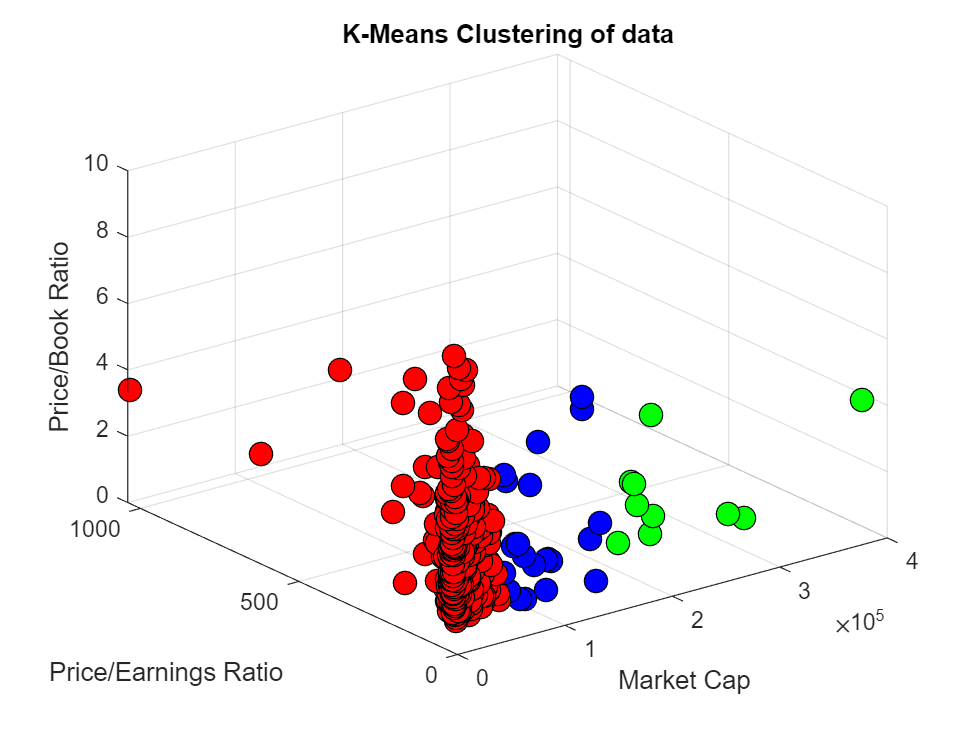

figure; plot3(FinData.MarketCap(idx==1),FinData.P_E(idx==1),FinData.P_B(idx==1),'o','Color','k','MarkerSize',10,'MarkerFaceColor','blue'); 
hold on; plot3(FinData.MarketCap(idx==2),FinData.P_E(idx==2),FinData.P_B(idx==2),'o','Color','k','MarkerSize',10,'MarkerFaceColor','g'); 
plot3(FinData.MarketCap(idx==3),FinData.P_E(idx==3),FinData.P_B(idx==3),'o','Color','k','MarkerSize',10,'MarkerFaceColor','r'); grid('on')
xlabel('Market Cap')
ylabel('Price/Earnings Ratio')
zlabel('Price/Book Ratio')
title('K-Means Clustering of data')